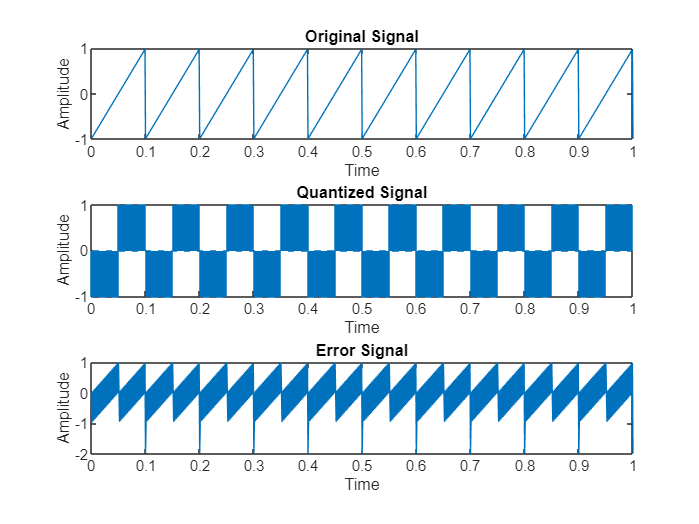


%ADM
%Signal Parameters
fs = 1000;
T = 1/fs;
t = 0:T:1;
fc = 10;
Ac = 1;
m = sawtooth(2*pi*fc*t);

%ADM parameters
L = 2;
delta = 0.5;
xhat(1) = 0;
n = length(m);

%ADM loop
for i=2:n
    e(i) = m(i) - xhat(i-1);
    if e(i)>=0
        d(i) = L;
    else
        d(i) = -L;
    end
    xhat(i) = xhat(i-1)+delta*d(i);
end

%plotting
subplot(3,1,1)
plot(t,m)
title('Original Signal')
xlabel('Time')
ylabel('Amplitude')
subplot(3,1,2)
stairs(t,xhat)
title('Quantized Signal')
xlabel('Time')
ylabel('Amplitude')
subplot(3,1,3)
plot(t,e)
title('Error Signal')
xlabel('Time')
ylabel('Amplitude')

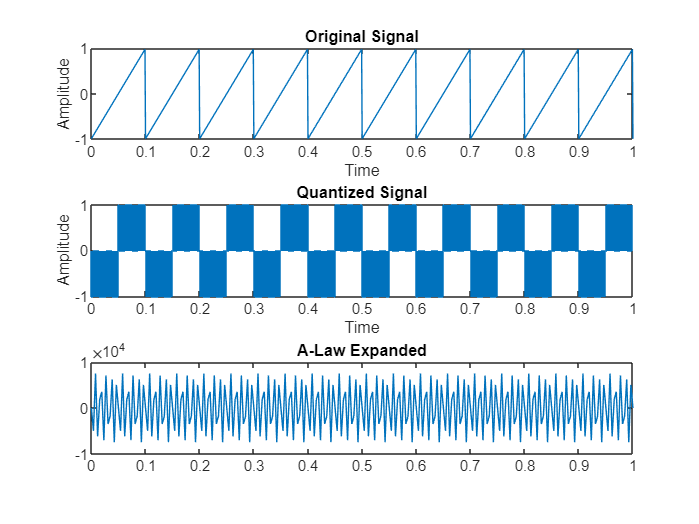

clear all
%Companding law
%signal parameter
fs = 260;
T = 1/fs;
t = 0:T:1;
f = 100;
A = 1;
x = A*sin(2*pi*f*t);

%uLaw companding
u = 255;
y_u = sign(x).*log(1+u*abs(x))/log(1+u);
x_u = sign(y_u).*((1+u).^abs(y_u)-1)/u;

%Alaw companding
Amax = 1;
A1 = 87.6;
A2 = 1/(1-A1);
y_A = sign(x).*log(1+A1*abs(x)/Amax)/log(1+A1);
x_A = sign(y_A).*((1+A1).^abs(y_A)-1)/(Amax*A2);

%plotting
plot(t,x)
title('Original Signal')
plot(t,y_u)
title('u-Law Companded')
plot(t,x_u)
title('u-Law Expanded')
plot(t,y_A)
title('A-Law Companded')
plot(t,x_A)
title('A-Law Expanded')

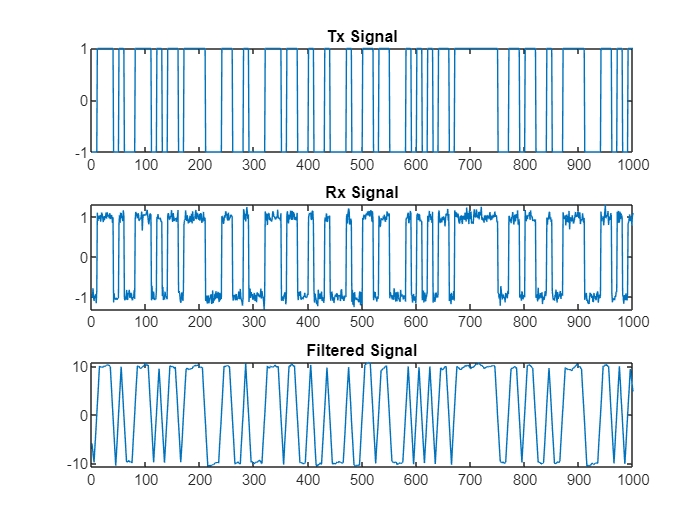

clear all
%Define the pulse shape
p_width = 10;
p_amplitude = 1;
p_shape = p_amplitude*ones(1,p_width);

%Define the signal to be transmitted
signal_length = 100;
signal = randi([0 1], 1, signal_length);
signal(signal==0) = -1;
txSig = kron(signal, p_shape);

%Add noise to the signal
noise_power = 0.01;
noise = sqrt(noise_power)*randn(size(txSig));
rxSig = txSig + noise;

%Define the matched filter
m_filter = fliplr(p_shape);

%Apply the matched filter to the received signal
filtered_signal = conv(rxSig, m_filter, 'same');

%Plot 
subplot(3,1,1)
plot(txSig)
title('Tx Signal')
subplot(3,1,2)
plot(rxSig)
title('Rx Signal')
subplot(3,1,3)
plot(filtered_signal)
title('Filtered Signal')


%%%

%haffman code
clc;
p=input('enter the probabilities:');
n= length(p);
symbols=[1:n];
[dict,avglen]=huffmandict(symbols,p);
temp=dict;
t=dict;
t=dict(:,2);
for i=1:length(temp)
    temp{i,2}=num2str(temp{i,2});
end
disp('the huffman code dict:');

the huffman code dict:


disp(temp)

    {[1]}    {'1'            }
    {[2]}    {'0  1'         }
    {[3]}    {'0  0  0'      }
    {[4]}    {'0  0  1  0'   }
    {[5]}    {'0  0  1  1  0'}
    {[6]}    {'0  0  1  1  1'}




fprintf('enter the symbols between 1 to %d in[]',n);

enter the symbols between 1 to 6 in[]

sym=input(':')

sym = 4

encod=huffmanenco(sym,dict);
disp('the encoded output:');

the encoded output:


disp(encod);

     0
     0
     1
     0



bits=input('enter the bit stream in[];');
decod=huffmandeco(bits,dict);
disp(decod);

     1     2





H=0;
Z=0;
for(k=1:n)
    H=H+(p(k)*log2(1/p(k)));
end
fprintf(1,'entropy is %f bits',H);

entropy is 1.975986 bits

N=H/avglen;
fprintf('\n efficency is:%f',N);


 efficency is:0.968620

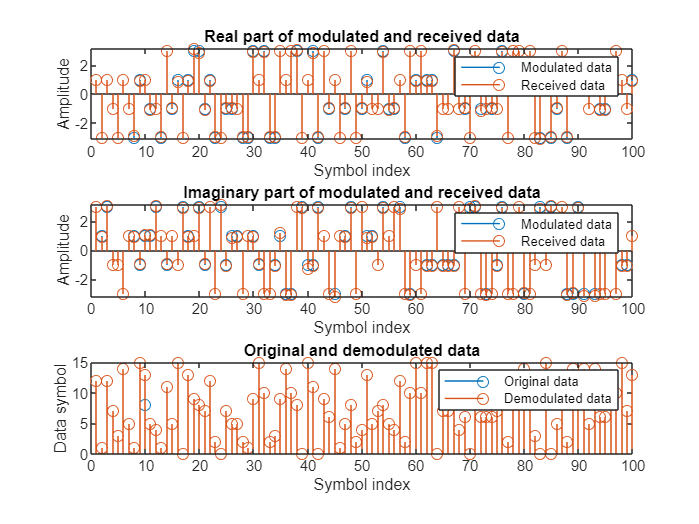

clear all
% Define the signal parameters
N = 100; % Number of symbols
M = 16; % Modulation order
pilot_idx = 10; % Index of the pilot symbol
pilot_value = 1 + 1i; % Value of the pilot symbol
SNR = 20; % Signal-to-Noise Ratio (dB)

% Generate the random data symbols
data = randi([0 M-1], 1, N);

% Modulate the data symbols
mod_data = qammod(data, M);

% Insert the pilot symbol
mod_data(pilot_idx) = pilot_value;

% Generate the noise
sigma2 = 10^(-SNR/10); % Noise variance
noise = sqrt(sigma2/2)*(randn(1,N)+1i*randn(1,N));

% Add the noise to the modulated data
rx_data = mod_data + noise;

% Estimate the channel using the pilot symbol
H_est = rx_data(pilot_idx)/pilot_value;

% Equalize the received data
eq_data = rx_data/H_est;

% Demodulate the received data
demod_data = qamdemod(eq_data, M);

% Calculate the entropy of the data symbols
p = histcounts(demod_data, 0:M-1, 'Normalization', 'probability');
entropy = -sum(p.*log2(p));

% Plot the results
subplot(3,1,1);
stem(real(mod_data));
hold on;
stem(real(rx_data));
title('Real part of modulated and received data');
legend('Modulated data', 'Received data');
xlabel('Symbol index');
ylabel('Amplitude');

subplot(3,1,2);
stem(imag(mod_data));
hold on;
stem(imag(rx_data));
title('Imaginary part of modulated and received data');
legend('Modulated data', 'Received data');
xlabel('Symbol index');
ylabel('Amplitude');

subplot(3,1,3);
stem(data);
hold on;
stem(demod_data);
title('Original and demodulated data');
legend('Original data', 'Demodulated data');
xlabel('Symbol index');
ylabel('Data symbol');


fprintf('Entropy of the data: %.4f bits/symbol\n', entropy);

Entropy of the data: 3.7587 bits/symbol
